# Tratamento inicial dos dados

## Zerar workspace

clear;

## Importar CSV dos dados

Os dados originais (CSV) devem ter sido tratados previamente (editar a hora para o formato YYYY-MM-DD hh:mm:ss, adicionar linha de cabeçalho, verificar numero de colunas)

node1 = readtable('logs/csv/coleta02_20170131_20170207/1/WMLOGB_edited.CSV');
node2 = readtable('logs/csv/coleta02_20170131_20170207/2/WMLOGB_edited.CSV');
node3 = readtable('logs/csv/coleta02_20170131_20170207/3/WMLOGB_edited.CSV');
node4 = readtable('logs/csv/coleta02_20170131_20170207/4/WMLOGB_edited.CSV');

% dados dos tensiometros analogicos (baterias 1 e 2)
load('/Users/andreibosco/Devel/git/smartgreen/matlab/logs/csv/tensiometros/2017-baterias1e2-T6.mat')

## Preenchendo dados ausentes com interpolação linear

bateria1.p15cmFilled = fillmissing(bateria1.p15cm,'linear');
bateria1.p45cmFilled = fillmissing(bateria1.p45cm,'linear');
bateria1.p75cmFilled = fillmissing(bateria1.p75cm,'linear');

bateria2.p15cmFilled = fillmissing(bateria2.p15cm,'linear');
bateria2.p45cmFilled = fillmissing(bateria2.p45cm,'linear');
bateria2.p75cmFilled = fillmissing(bateria2.p75cm,'linear');

## Gerando tabela com média das leituras dos tensiômetros das duas baterias de tratamentos

Date = bateria1.Date;
baterias_p15cm = [bateria1.p15cmFilled bateria2.p15cmFilled];
baterias_p15cmMean = mean(baterias_p15cm,2);
baterias_p45cm = [bateria1.p45cmFilled bateria2.p45cmFilled];
baterias_p45cmMean = mean(baterias_p45cm,2);
baterias_p75cm = [bateria1.p75cmFilled bateria2.p75cmFilled];
baterias_p75cmMean = mean(baterias_p75cm,2);
baterias_Mean = table(Date, baterias_p15cmMean, baterias_p45cmMean, baterias_p75cmMean);

## Ajustando dados do sensor 03 do nó 4

Multiplicando por -1 para tornar os valores positivos

*FIXME: decidir se essa multiplicação será feita ou não*

% node4.sensor03value = node4.sensor03value * -1;

## Converter tabelas em timetables

node1 = table2timetable(node1);
node2 = table2timetable(node2);
node3 = table2timetable(node3);
node4 = table2timetable(node4);

## Conversão dos dados dos sensores de Ohm para cbar/kPa

utilizando a formula que leva em consideração a temperatura do solo

*Detalhe: a temperatura utilizada não é do solo, mas do sensor RTC*

% wmlog_node1.sensor01cbar = (3.213*(wmlog_node1.sensor01value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor01value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor02cbar = (3.213*(wmlog_node1.sensor02value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor02value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor03cbar = (3.213*(wmlog_node1.sensor03value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor03value./1000)-0.01205*wmlog_node1.temperature)

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizanda a fórmula básica de conversão da irrometer)

node1{:,3:end} = (node1{:,3:end}-550)./137.5;
node2{:,3:end} = (node2{:,3:end}-550)./137.5;
node3{:,3:end} = (node3{:,3:end}-550)./137.5;
node4{:,3:end} = (node4{:,3:end}-550)./137.5;

## Tornando os valores negativos em positivos

node1{:,3:end} = abs(node1{:,3:end});
node2{:,3:end} = abs(node2{:,3:end});
node3{:,3:end} = abs(node3{:,3:end});
node4{:,3:end} = abs(node4{:,3:end});

## Determinar período de tempo a ser utilizado e filtrar tabelas

%range = timerange('2017-01-31', '2017-02-07');
%node1 = node1(range,:);
%node2 = node2(range,:);
%node4 = node4(range,:);

**FIXME**: ajustes de escala (sensor de 15cm dos nós 1 e 2 estão em uma ordem de grandeza maior, não sei o motivo)

% node1.sensor01cbar = node1.sensor01cbar/100;
% node2.sensor01cbar = node2.sensor01cbar/100;
node1{:,3:26} = node1{:,3:26}/100;
node2{:,3:26} = node2{:,3:26}/100;

## **Ajuste da calibração dos dados**

**FIXME: verificar ****se a redução a seguir é mesmo necessária**

Segundo a documentação dos sensores watermark irrometer, eles foram calibrados para funcionar a 70ºF. A cada grau F acima de 70 é necessário reduzir a leitura em 1%

Considerando o solo a 32ºC (89.6ºF)

soil_temp = 89.6;
sensor_adjustment = (100 - (soil_temp - 70))/100;

node1{:,3:end} = node1{:,3:end} * sensor_adjustment;
node2{:,3:end} = node2{:,3:end} * sensor_adjustment;
node3{:,3:end} = node3{:,3:end} * sensor_adjustment;
node4{:,3:end} = node4{:,3:end} * sensor_adjustment;

## Equilibrando dados dos nós

Removendo dados além de 2017-01-05 10:00 (último momento com dados dos 4 nós) e a primeira medição dos nós 1, 2 e 3

% node1(122:end,:) = [];
% node2(122:end,:) = [];
% node3(122:end,:) = [];
% node4(122:end,:) = [];

% removendo dados após a morte do segundo nó
node1(153:end,:) = [];
node2(153:end,:) = [];
node3(153:end,:) = [];
node4(153:end,:) = [];

% removendo primeira medição para que todos comecem iguais
node1(1,:) = [];
node2(1,:) = [];
node3(1,:) = [];
node4(1,:) = [];

## Cálculo: Nova média

Calculando novas médias para todos os nós e sensores

node1.sensor01mean = mean(node1{1:end,5:26},2,'omitnan');
node1.sensor02mean = mean(node1{1:end,29:50},2,'omitnan');
node1.sensor03mean = mean(node1{1:end,53:74},2,'omitnan');

node2.sensor01mean = mean(node2{1:end,5:26},2,'omitnan');
node2.sensor02mean = mean(node2{1:end,29:50},2,'omitnan');
node2.sensor03mean = mean(node2{1:end,53:74},2,'omitnan');

node3.sensor01mean = mean(node3{1:end,5:26},2,'omitnan');
node3.sensor02mean = mean(node3{1:end,29:50},2,'omitnan');
node3.sensor03mean = mean(node3{1:end,53:74},2,'omitnan');

node4.sensor01mean = mean(node4{1:end,5:26},2,'omitnan');
node4.sensor02mean = mean(node4{1:end,29:50},2,'omitnan');
node4.sensor03mean = mean(node4{1:end,53:74},2,'omitnan');


## Cálculo: Mediana

Calculando medianas para todos os nós e sensores

node1.sensor01median = median(node1{1:end,5:26},2,'omitnan');
node1.sensor02median = median(node1{1:end,29:50},2,'omitnan');
node1.sensor03median = median(node1{1:end,53:74},2,'omitnan');

node2.sensor01median = median(node2{1:end,5:26},2,'omitnan');
node2.sensor02median = median(node2{1:end,29:50},2,'omitnan');
node2.sensor03median = median(node2{1:end,53:74},2,'omitnan');

node3.sensor01median = median(node3{1:end,5:26},2,'omitnan');
node3.sensor02median = median(node3{1:end,29:50},2,'omitnan');
node3.sensor03median = median(node3{1:end,53:74},2,'omitnan');

node4.sensor01median = median(node4{1:end,5:26},2,'omitnan');
node4.sensor02median = median(node4{1:end,29:50},2,'omitnan');
node4.sensor03median = median(node4{1:end,53:74},2,'omitnan');

## Unificando dados dos sensores dos nós

sensor1meanOrig = [node1.sensor01value node2.sensor01value node3.sensor01value node4.sensor01value];
sensor2meanOrig = [node1.sensor02value node2.sensor02value node3.sensor02value node4.sensor02value];
sensor3meanOrig = [node1.sensor03value node2.sensor03value node3.sensor03value node4.sensor03value];

sensor1mean = [node1.sensor01mean node2.sensor01mean node3.sensor01mean node4.sensor01mean];
sensor2mean = [node1.sensor02mean node2.sensor02mean node3.sensor02mean node4.sensor02mean];
sensor3mean = [node1.sensor03mean node2.sensor03mean node3.sensor03mean node4.sensor03mean];

sensor1median = [node1.sensor01median node2.sensor01median node3.sensor01median node4.sensor01median];
sensor2median = [node1.sensor02median node2.sensor02median node3.sensor02median node4.sensor02median];
sensor3median = [node1.sensor03median node2.sensor03median node3.sensor03median node4.sensor03median];


Convertendo NaN para 0

sensor1meanOrigB = sensor1meanOrig;
sensor1meanOrigB(121:151,3) = 0;

sensor2meanOrigB = sensor2meanOrig;
sensor2meanOrigB(121:151,3) = 0;

sensor3meanOrigB = sensor3meanOrig;
sensor3meanOrigB(121:151,3) = 0;

FIXME TEMP: convertendo dados vazios do nó 3 sensor 1 para NaN

% sensor1meanOrig(121:151,3) = 0;
% sensor2meanOrig(121:151,3) = 0;
% sensor3meanOrig(121:151,3) = 0;
% 
% sensor1mean(121:151,3) = 0;
% sensor2mean(121:151,3) = 0;
% sensor3mean(121:151,3) = 0;
% 
% sensor1median(121:151,3) = 0;
% sensor2median(121:151,3) = 0;
% sensor3median(121:151,3) = 0;

sensor1meanOrig(121:151,3) = NaN;
sensor2meanOrig(121:151,3) = NaN;
sensor3meanOrig(121:151,3) = NaN;

sensor1mean(121:151,3) = NaN;
sensor2mean(121:151,3) = NaN;
sensor3mean(121:151,3) = NaN;

sensor1median(121:151,3) = NaN;
sensor2median(121:151,3) = NaN;
sensor3median(121:151,3) = NaN;

## Configuração de plotagem dos gráficos

Determinar variáveis para plotar linhas de indicação de umidade do solo

% DateStrings = {'2017-01-31';'2017-02-05'};
% t = datetime(DateStrings,'InputFormat','yyyy-MM-dd');
dateRange = node1.time;
% dateRange(122:end,:) = [];
dateRange(152:end,:) = [];
dateRangeString = cellstr(dateRange);

% indicativo da morte do nó 3
global dateSensorDeath;
dateSensorDeath = datetime({'2017-02-05 10:00'},'InputFormat','yyyy-MM-dd hh:mm');

Informação de saturação do solo:

- 0 a 10: solo saturado

- 10 a 30: solo adequadamente umido (exceto areia fina)

- 30 a 60: necessita rega

- 60 a 100: necessita rega (barro pesado)

- 100 a 200: perigosamente seco

# Fusão

## Gráfico: Média original

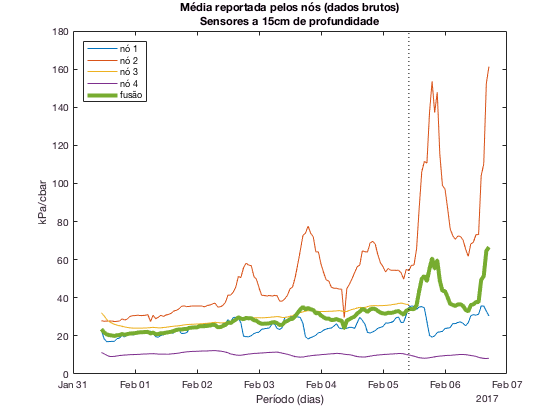

sensor1fusedMean = basicFusion(sensor1meanOrig,'mean');
sensor2fusedMean = basicFusion(sensor2meanOrig,'mean');
sensor3fusedMean = basicFusion(sensor3meanOrig,'mean');

plotar_sensores(dateRange,sensor1meanOrig,sensor1fusedMean,...
    '15cm','media_original','Média reportada pelos nós (dados brutos)','northwest');

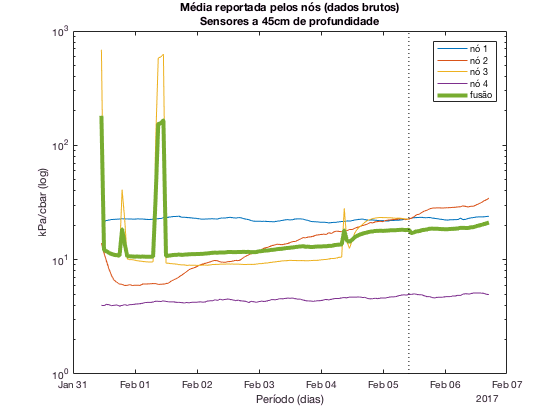

plotar_sensores(dateRange,sensor2meanOrig,sensor2fusedMean,...
    '45cm','media_original','Média reportada pelos nós (dados brutos)','northeast',true);

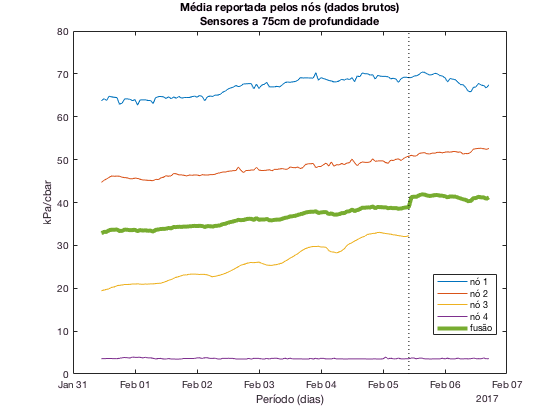

plotar_sensores(dateRange,sensor3meanOrig,sensor3fusedMean,...
    '75cm','media_original','Média reportada pelos nós (dados brutos)',[0.78 0.25 0.10 0.05]);

## Média nova

Média normal dos dados dos sensores

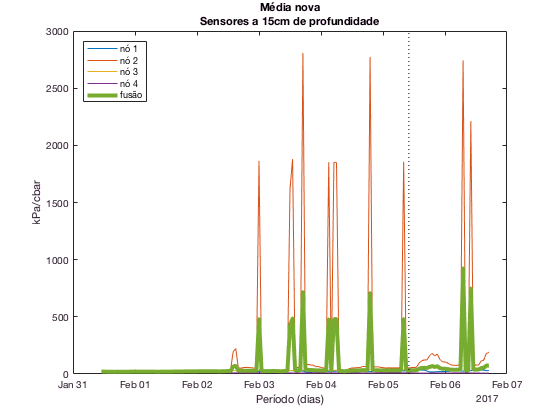

sensor1fusedMeanNew = basicFusion(sensor1mean,'mean');
sensor2fusedMeanNew = basicFusion(sensor2mean,'mean');
sensor3fusedMeanNew = basicFusion(sensor3mean,'mean');

plotar_sensores(dateRange,sensor1mean,sensor1fusedMeanNew,...
    '15cm','media_nova','Média nova','northwest');

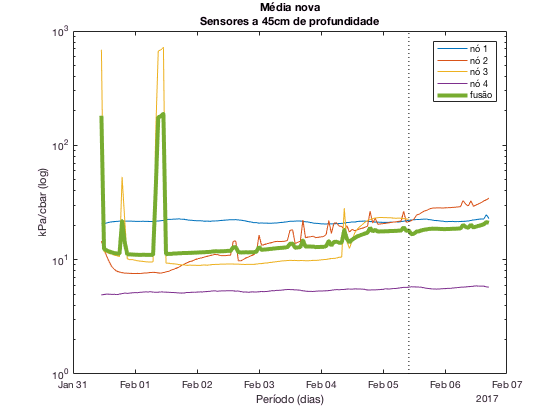

plotar_sensores(dateRange,sensor2mean,sensor2fusedMeanNew,...
    '45cm','media_nova','Média nova','northeast',true);

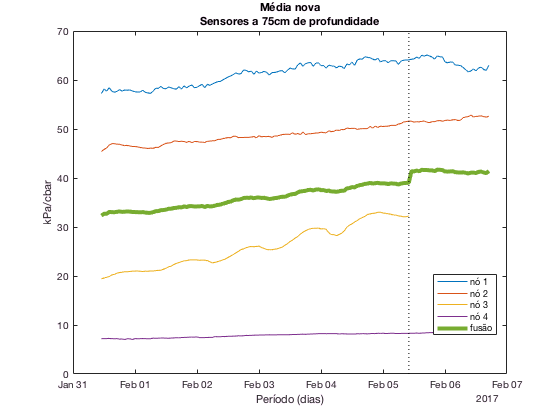

plotar_sensores(dateRange,sensor3mean,sensor3fusedMeanNew,...
    '75cm','media_nova','Média nova',[0.78 0.25 0.10 0.05]);

## Mediana

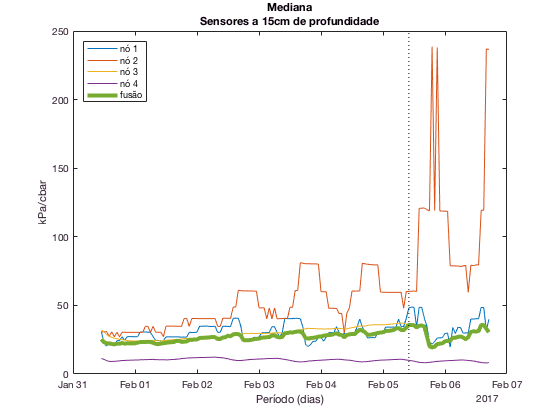

sensor1fusedMedian = basicFusion(sensor1meanOrig,'median');
sensor2fusedMedian = basicFusion(sensor2meanOrig,'median');
sensor3fusedMedian = basicFusion(sensor3meanOrig,'median');

plotar_sensores(dateRange,sensor1median,sensor1fusedMedian,...
    '15cm','mediana','Mediana','northwest');

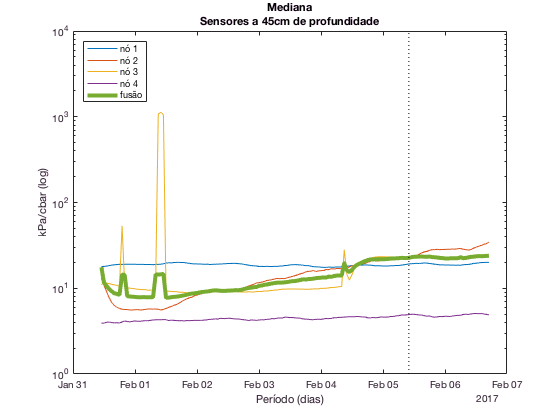

plotar_sensores(dateRange,sensor2median,sensor2fusedMedian,...
    '45cm','mediana','Mediana','northwest',true);

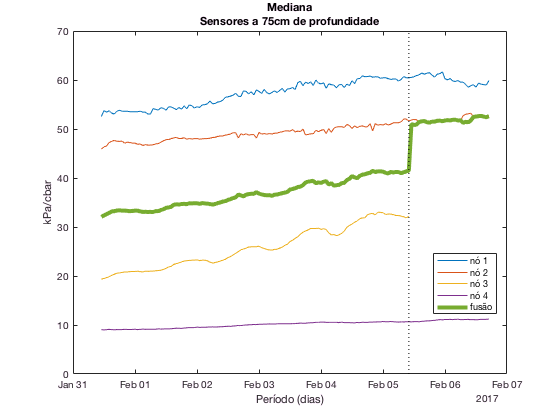

plotar_sensores(dateRange,sensor3median,sensor3fusedMedian,...
    '75cm','mediana','Mediana',[0.78 0.3 0.10 0.05]);

## Comparativo entre médias originais e novas

Comparativo sensor de 15cm

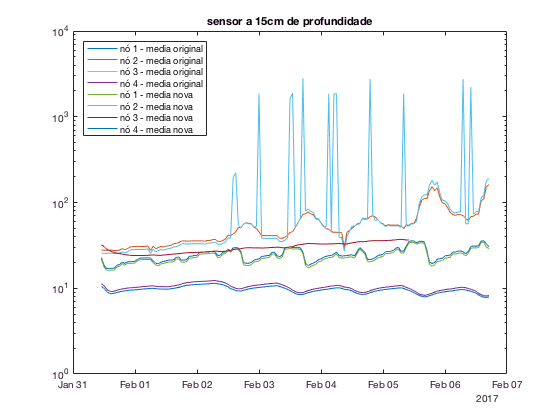

comparativo15 = figure;
semilogy(dateRange,sensor1meanOrig);
hold on
semilogy(dateRange,sensor1mean);
hold off
legend('nó 1 - media original','nó 2 - media original','nó 3 - media original','nó 4 - media original','nó 1 - media nova','nó 2 - media nova','nó 3 - media nova','nó 4 - media nova','Location','best')
title('sensor a 15cm de profundidade')
saveas(comparativo15,'graphs/comparativo_15cm','png')

Comparativo sensor de 45cm

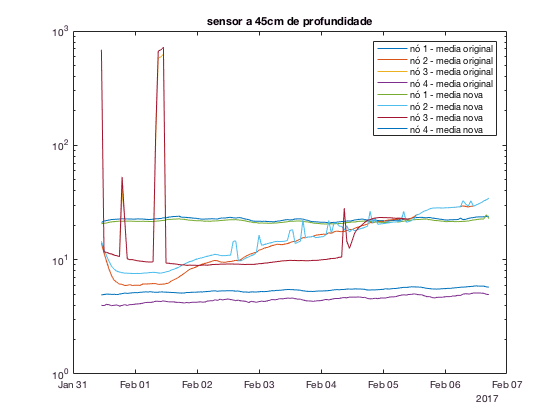

comparativo45 = figure;
semilogy(dateRange,sensor2meanOrig);
hold on
semilogy(dateRange,sensor2mean);
hold off
legend('nó 1 - media original','nó 2 - media original','nó 3 - media original','nó 4 - media original','nó 1 - media nova','nó 2 - media nova','nó 3 - media nova','nó 4 - media nova','Location','northeast')
title('sensor a 45cm de profundidade')
saveas(comparativo45,'graphs/comparativo_45cm','png')

Comparativo sensor de 75cm

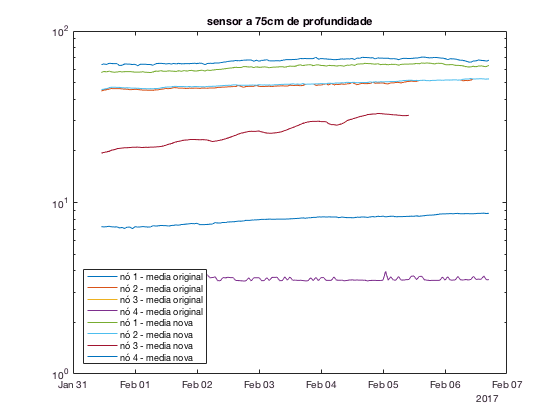

comparativo75 = figure;
semilogy(dateRange,sensor3meanOrig);
hold on
semilogy(dateRange,sensor3mean);
hold off
legend('nó 1 - media original','nó 2 - media original','nó 3 - media original','nó 4 - media original','nó 1 - media nova','nó 2 - media nova','nó 3 - media nova','nó 4 - media nova','Location','best')
title('sensor a 75cm de profundidade')
saveas(comparativo75,'graphs/comparativo_75cm','png')

## Peirce

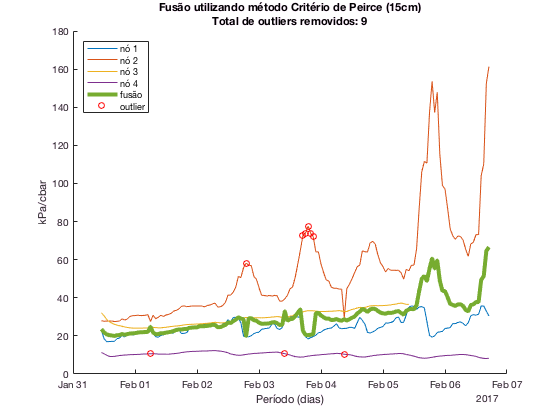

[sensor1fusedPeirce, sensor1peirceOutliers, sensor1peirceOutliersTotal] = peirceFusion(sensor1meanOrig);
[sensor2fusedPeirce, sensor2peirceOutliers, sensor2peirceOutliersTotal] = peirceFusion(sensor2meanOrig);
[sensor3fusedPeirce, sensor3peirceOutliers, sensor3peirceOutliersTotal] = peirceFusion(sensor3meanOrig);

plotar_metodo_alt(dateRange,sensor1meanOrig,sensor1fusedPeirce,...
    '15cm_fusao_peirce','Critério de Peirce (15cm)',sensor1peirceOutliersTotal,'northwest',sensor1peirceOutliers);

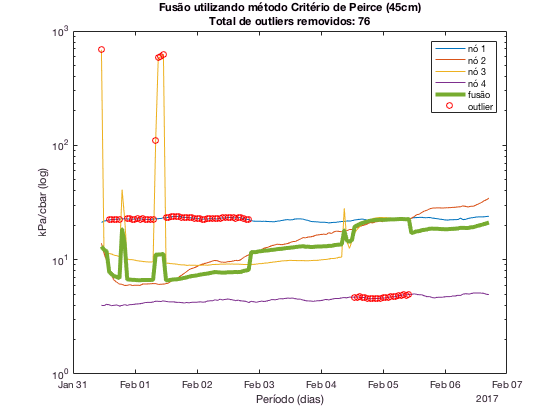

plotar_metodo_alt_log(dateRange,sensor2meanOrig,sensor2fusedPeirce,...
    '45cm_fusao_peirce','Critério de Peirce (45cm)',sensor2peirceOutliersTotal,'northeast',sensor2peirceOutliers);

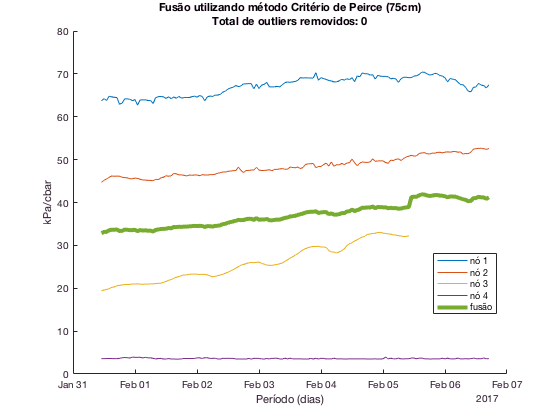

plotar_metodo_alt(dateRange,sensor3meanOrig,sensor3fusedPeirce,...
    '75cm_fusao_peirce','Critério de Peirce (75cm)',sensor3peirceOutliersTotal,[0.78 0.3 0.10 0.05],sensor3peirceOutliers);

## Chauvenet

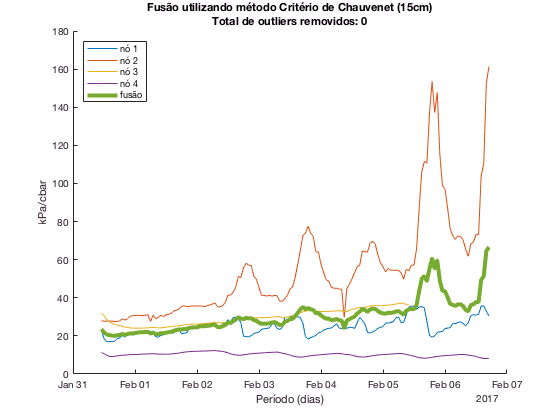

[sensor1fusedChauvenet, sensor1chauvenetOutliers, sensor1chauvenetOutliersTotal] = chauvenetFusion(sensor1meanOrig);
[sensor2fusedChauvenet, sensor2chauvenetOutliers, sensor2chauvenetOutliersTotal] = chauvenetFusion(sensor2meanOrig);
[sensor3fusedChauvenet, sensor3chauvenetOutliers, sensor3chauvenetOutliersTotal] = chauvenetFusion(sensor3meanOrig);

plotar_metodo(dateRange,sensor1meanOrig,sensor1fusedChauvenet,...
    '15cm_fusao_chauvenet','Critério de Chauvenet (15cm)',sensor1chauvenetOutliersTotal,'northwest',sensor1chauvenetOutliers);

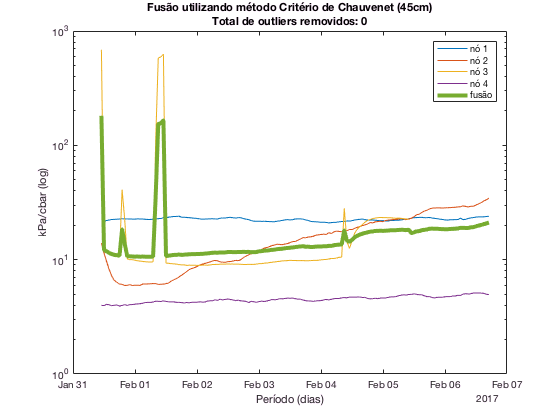

plotar_metodo_log(dateRange,sensor2meanOrig,sensor2fusedChauvenet,...
    '45cm_fusao_chauvenet','Critério de Chauvenet (45cm)',sensor2chauvenetOutliersTotal,'northeast',sensor2chauvenetOutliers);

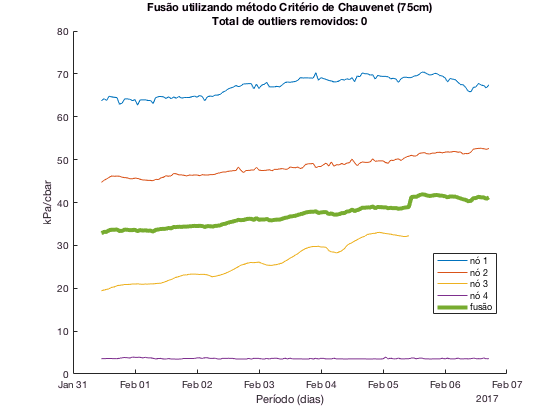

plotar_metodo(dateRange,sensor3meanOrig,sensor3fusedChauvenet,...
    '75cm_fusao_chauvenet','Critério de Chauvenet (75cm)',sensor3chauvenetOutliersTotal,[0.78 0.3 0.10 0.05],sensor3chauvenetOutliers);

## Z-score

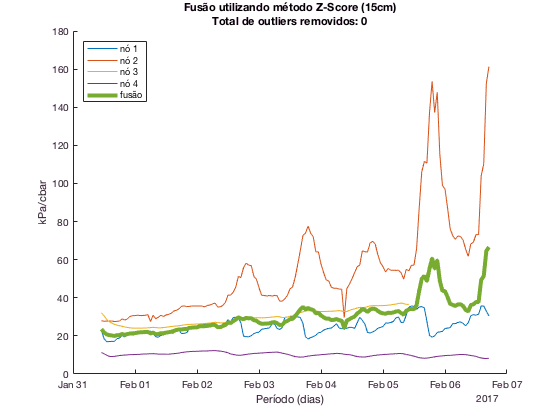

% threshold padrão de 3.0 alterado para 1.4, do contrário nenhum outlier teria sido detectado, nem mesmo os mais extremos. Ex.: sensor1meanT(62,:)
[sensor1fusedZScore, sensor1zScoreOutliersIndex, sensor1zScoreOutliersTotal, sensor1zScores] = zScoreFusion(sensor1meanOrig,dateRangeString,3.0);
[sensor2fusedZScore, sensor2zScoreOutliersIndex, sensor2zScoreOutliersTotal, sensor2zScores] = zScoreFusion(sensor2meanOrig,dateRangeString,3.0);
[sensor3fusedZScore, sensor3zScoreOutliersIndex, sensor3zScoreOutliersTotal, sensor3zScores] = zScoreFusion(sensor3meanOrig,dateRangeString,3.0);

plotar_metodo(dateRange,sensor1meanOrig,sensor1fusedZScore,...
    '15cm_fusao_zScore','Z-Score (15cm)',sensor1zScoreOutliersTotal,'northwest',sensor1zScoreOutliersIndex);

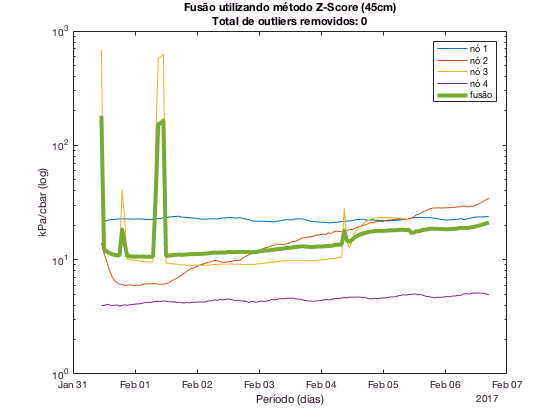

plotar_metodo_log(dateRange,sensor2meanOrig,sensor2fusedZScore,...
    '45cm_fusao_zScore','Z-Score (45cm)',sensor2zScoreOutliersTotal,'northeast',sensor2zScoreOutliersIndex);

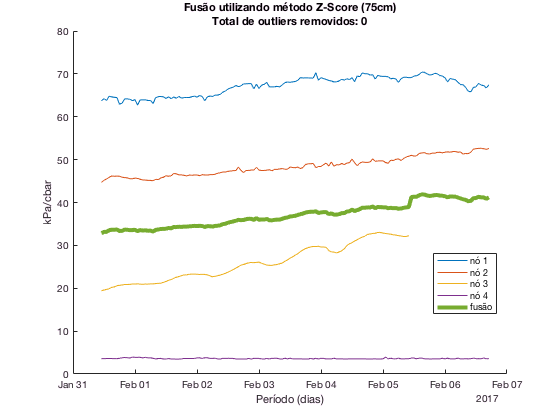

plotar_metodo(dateRange,sensor3meanOrig,sensor3fusedZScore,...
    '75cm_fusao_zScore','Z-Score (75cm)',sensor3zScoreOutliersTotal,[0.78 0.3 0.10 0.05],sensor3zScoreOutliersIndex);

## ESD

% ultimo parâmetro é a quantidade máxima esperada de outliers
[sensor1fusedESD, sensor1ESDOutliersIndex, sensor1ESDOutliersTotal] = gesdFusion(sensor1meanOrig,dateRangeString,3);
[sensor2fusedESD, sensor2ESDOutliersIndex, sensor2ESDOutliersTotal] = gesdFusion(sensor2meanOrig,dateRangeString,3);
[sensor3fusedESD, sensor3ESDOutliersIndex, sensor3ESDOutliersTotal] = gesdFusion(sensor3meanOrig,dateRangeString,3);

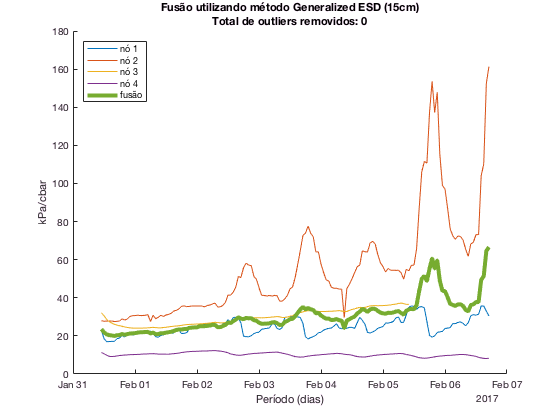

plotar_metodo_alt(dateRange,sensor1meanOrig,sensor1fusedESD,...
    '15cm_fusao_ESD','Generalized ESD (15cm)',sensor1ESDOutliersTotal,'northwest',sensor1ESDOutliersIndex);

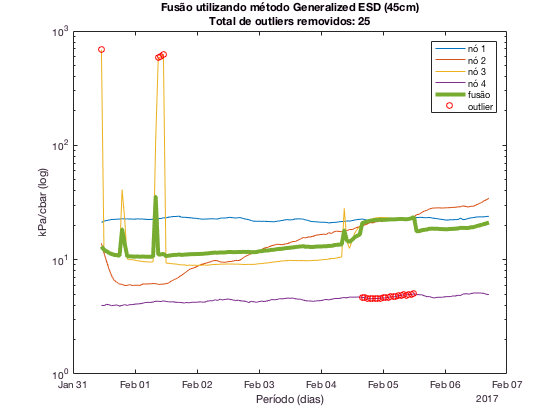

plotar_metodo_alt_log(dateRange,sensor2meanOrig,sensor2fusedESD,...
    '45cm_fusao_ESD','Generalized ESD (45cm)',sensor2ESDOutliersTotal,'northeast',sensor2ESDOutliersIndex);

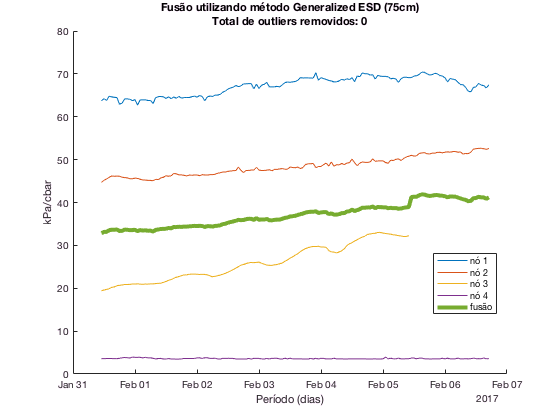

plotar_metodo_alt(dateRange,sensor3meanOrig,sensor3fusedESD,...
    '75cm_fusao_ESD','Generalized ESD (75cm)',sensor3ESDOutliersTotal,[0.78 0.3 0.10 0.05],sensor3ESDOutliersIndex);

## Modified Z-score

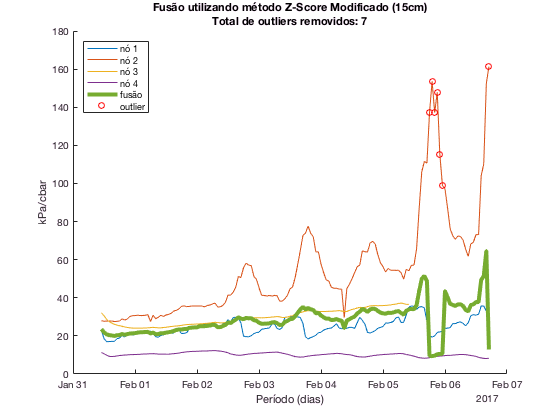

% threshold padrão de 3.5 foi mantido
[sensor1fusedMZScore, sensor1mzScoreOutliersIndex, sensor1mzScoreOutliersTotal, sensor1mzScores] = mzScoreFusion(sensor1meanOrig,dateRangeString,3.5);
[sensor2fusedMZScore, sensor2mzScoreOutliersIndex, sensor2mzScoreOutliersTotal, sensor2mzScores] = mzScoreFusion(sensor2meanOrig,dateRangeString,3.5);
[sensor3fusedMZScore, sensor3mzScoreOutliersIndex, sensor3mzScoreOutliersTotal, sensor3mzScores] = mzScoreFusion(sensor3meanOrig,dateRangeString,3.5);

plotar_metodo(dateRange,sensor1meanOrig,sensor1fusedMZScore,...
    '15cm_fusao_ZScoreModif','Z-Score Modificado (15cm)',sensor1mzScoreOutliersTotal,'northwest',sensor1mzScoreOutliersIndex);

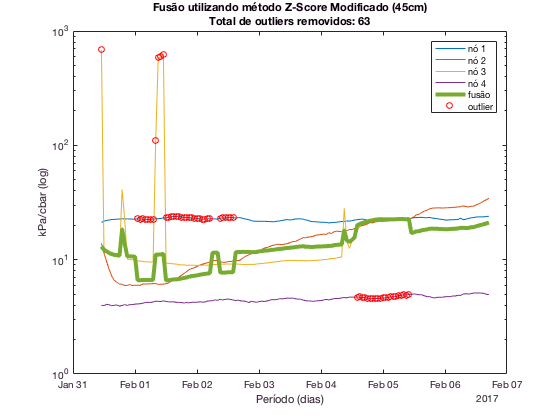

plotar_metodo_log(dateRange,sensor2meanOrig,sensor2fusedMZScore,...
    '45cm_fusao_ZScoreModif','Z-Score Modificado (45cm)',sensor2mzScoreOutliersTotal,'northeast',sensor2mzScoreOutliersIndex);

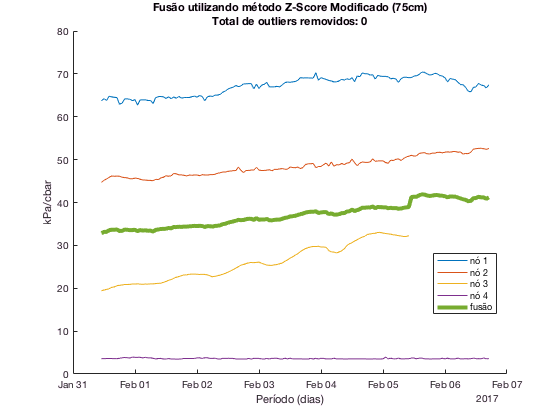

plotar_metodo(dateRange,sensor3meanOrig,sensor3fusedMZScore,...
    '75cm_fusao_ZScoreModif','Z-Score Modificado (75cm)',sensor3mzScoreOutliersTotal,[0.78 0.3 0.10 0.05],sensor3mzScoreOutliersIndex);

## Adjusted boxplot

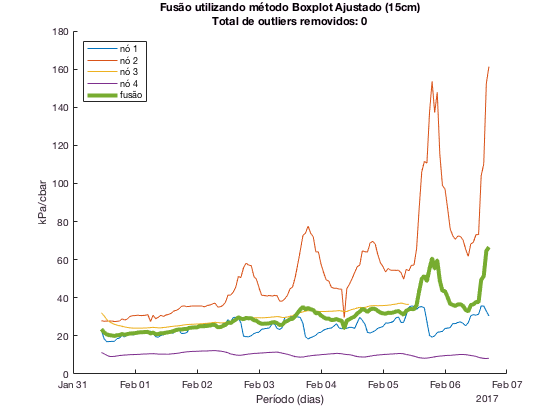

% threshold padrão de 1.5
[sensor1fusedBoxAdj, sensor1boxAdjScores, sensor1boxAdjOutliers, sensor1boxAdjOutliersTotal] = adjboxplotFusion2(sensor1meanOrig,3.5);
[sensor2fusedBoxAdj, sensor2boxAdjScores, sensor2boxAdjOutliers, sensor2boxAdjOutliersTotal] = adjboxplotFusion2(sensor2meanOrig,3.5);
[sensor3fusedBoxAdj, sensor3boxAdjScores, sensor3boxAdjOutliers, sensor3boxAdjOutliersTotal] = adjboxplotFusion2(sensor3meanOrig,3.5);

plotar_metodo_alt(dateRange,sensor1meanOrig,sensor1fusedBoxAdj,...
    '15cm_fusao_boxplotAdj','Boxplot Ajustado (15cm)',sensor1boxAdjOutliersTotal,'northwest',sensor1boxAdjOutliers);

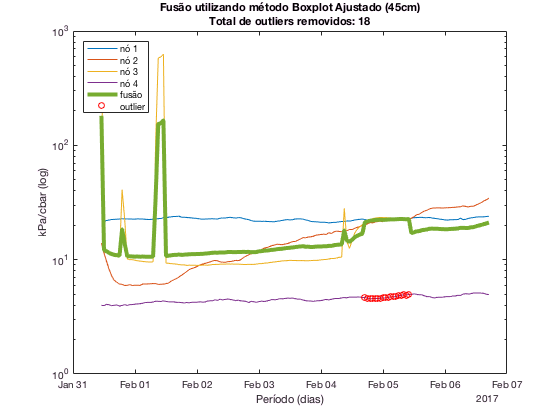

plotar_metodo_alt_log(dateRange,sensor2meanOrig,sensor2fusedBoxAdj,...
    '45cm_fusao_boxplotAdj','Boxplot Ajustado (45cm)',sensor2boxAdjOutliersTotal,'northwest',sensor2boxAdjOutliers);

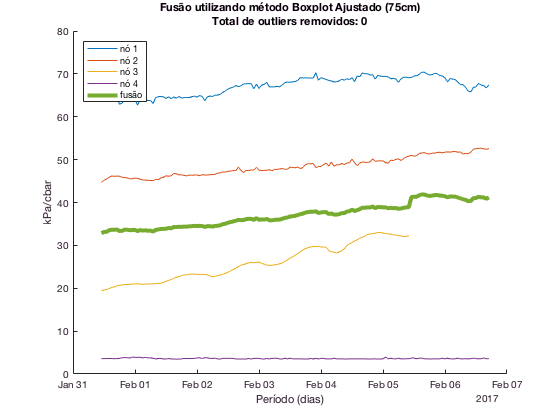

plotar_metodo_alt(dateRange,sensor3meanOrig,sensor3fusedBoxAdj,...
    '75cm_fusao_boxplotAdj','Boxplot Ajustado (75cm)',sensor3boxAdjOutliersTotal,'northwest',sensor3boxAdjOutliers);

## Modified boxplot alt

% threshold padrão de 1.5
% [sensor1fusedBoxAdj, sensor1boxAdjScores, sensor1boxAdjOutliers, sensor1boxAdjOutliersTotal] = adjboxplotFusion2(sensor1meanOrig,3.5);
% [sensor2fusedBoxAdj, sensor2boxAdjScores, sensor2boxAdjOutliers, sensor2boxAdjOutliersTotal] = adjboxplotFusion2(sensor2meanOrig,3.5);
% [sensor3fusedBoxAdj, sensor3boxAdjScores, sensor3boxAdjOutliers, sensor3boxAdjOutliersTotal] = adjboxplotFusion2(sensor3meanOrig,3.5);
% 
% plotar_metodo_alt(dateRange,sensor1meanOrig,sensor1fusedBoxAdj,...
%     '15cm_fusao_boxplotAdj','Boxplot Ajustado (15cm)',sensor1boxAdjOutliersTotal,'northwest',sensor1boxAdjOutliers);
% plotar_metodo_alt_log(dateRange,sensor2meanOrig,sensor2fusedBoxAdj,...
%     '45cm_fusao_boxplotAdj','Boxplot Ajustado (45cm)',sensor2boxAdjOutliersTotal,'northwest',sensor2boxAdjOutliers);
% plotar_metodo_alt(dateRange,sensor3meanOrig,sensor3fusedBoxAdj,...
%     '75cm_fusao_boxplotAdj','Boxplot Ajustado (75cm)',sensor3boxAdjOutliersTotal,'northwest',sensor3boxAdjOutliers);

## Filtro de Kalman

## Variancia

var1 = var(node1{14:38,5:15},1,2,'omitnan');
mean(var1);
var2 = var(node2{14:38,5:15},1,2,'omitnan');
mean(var2);
var3 = var(node3{14:38,5:15},1,2,'omitnan');
mean(var3);
var4 = var(node4{14:38,5:15},1,2,'omitnan');
mean(var4);

% variancia de todas as linhas
% sensor1var = [var(node1{1:end,5:15},1,2,'omitnan') var(node2{1:end,5:15},1,2,'omitnan')' var(node3{1:end,5:15},1,2,'omitnan')' var(node4{1:end,5:15},1,2,'omitnan')'];
% var2 = var(node2{1:end,5:15},1,2,'omitnan')';
% var3 = var(node3{1:end,5:15},1,2,'omitnan')';
% var4 = var(node4{1:end,5:15},1,2,'omitnan')';

## Parâmetros

Covariância do ruídos das medições *#FIXME: falta atualizar esses valores. Utilizan**do os valores do exemplo.*

% for our single-sensor example, we defined 'r' as the variance of the observation
% noise signal 'vk'; that is, how much it varies around its mean (average) value.
% For a system with more than two sensors, 'R' is a matrix containing the 
% covariance between each pair of sensors

% Let's say that we've observed both our thermometers under climate-controlled
% conditions of steady temperature, and observed that their values fluctuate by
% an average of 0.8 degrees; i.e., the standard deviation of their readings is
% 0.8, making the variance 0.8 * 0.8 = 0.64
% R = [R1 0 0 0
%      0 R2 0 0
%      0 0 R3 0
%      0 0 0 R4]
% R1 = 0.8775;
% R2 = 4.2008;
% % R3 = 0.0024;
% R3 = 0.24;
% % R4 = 0.0040;
% R4 = 0.4;
R1 = 1 * 1;
R2 = R1;
R3 = R1;
R4 = R1;

Covariância do ruído do processo *#FIXME: falta** atualizar esse valor. Utilizando o valor do exemplo.*

Q = .005;

Estado do modelo de transição. Como o estado anterior não é conhecido então se inicia em 1

% we'll assume we have no knowledge of the state-transition model
% ('A' matrix) and so have to rely only on the sensor values
A = 1;

Modelo de observação (qual o grau de influencia dos dados do sensores na estimativa dos dados. Max: 1)

% We'll assume that both sensors contribute equally to our temperature estimation,
% so our CC matrix is just a pair of 1's
C1 = 1;
C2 = 1;
C3 = 1;
C4 = 1;

% gerando transpostas para facilitar o uso do filtro
sensor1kalman = sensor1meanOrigB';
sensor2kalman = sensor2meanOrigB';
sensor3kalman = sensor3meanOrigB';

% 1 sensor
sensor1fusedKAF1 = kalman([sensor1kalman(1,:)], A, C1, R1, Q);
sensor2fusedKAF1 = kalman([sensor2kalman(1,:)], A, C1, R1, Q);

% 2 sensores
sensor1fusedKAF2 = kalman([sensor1kalman(1,:); sensor1kalman(2,:)], A, [C1; C2], [R1 0; 0 R2], Q);
sensor2fusedKAF2 = kalman([sensor2kalman(1,:); sensor2kalman(2,:)], A, [C1; C2], [R1 0; 0 R2], Q);

% 3 sensores
sensor1fusedKAF3 = kalman([sensor1kalman(1,:); sensor1kalman(2,:); sensor1kalman(3,:)], A, [C1; C2; C3], [R1 0 0; 0 R2 0; 0 0 R3], Q);
sensor2fusedKAF3 = kalman([sensor2kalman(1,:); sensor2kalman(2,:); sensor2kalman(3,:)], A, [C1; C2; C3], [R1 0 0; 0 R2 0; 0 0 R3], Q);

% 4 sensores
sensor1fusedKAF4 = kalman([sensor1kalman(1,:); sensor1kalman(2,:); sensor1kalman(3,:); sensor1kalman(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);
sensor2fusedKAF4 = kalman([sensor2kalman(1,:); sensor2kalman(2,:); sensor2kalman(3,:); sensor2kalman(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);
sensor3fusedKAF4 = kalman([sensor3kalman(1,:); sensor3kalman(2,:); sensor3kalman(3,:); sensor3kalman(4,:)], A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);

% utilizando modified z-score como base
sensor1kalmanAlt = sensor1fusedESD';
sensor2kalmanAlt = sensor2fusedESD';
sensor3kalmanAlt = sensor3fusedESD';
sensor1fusedKAFalt = kalman([sensor1kalmanAlt(1,:)], A, C1, R1, Q);
sensor2fusedKAFalt = kalman([sensor2kalmanAlt(1,:)], A, C1, R1, Q);
sensor3fusedKAFalt = kalman([sensor3kalmanAlt(1,:)], A, C1, R1, Q);

# Gráficos

## Comparação Kalman

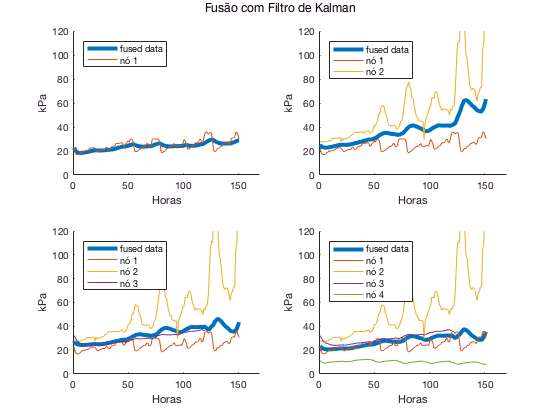

clf % clear current figure
kalmanSubplot = figure;
a = subplot(2,2,1);
hold on
plot(sensor1fusedKAF1,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01value,'DisplayName','nó 1')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
% title(a,'1 nó')
hold off

b = subplot(2,2,2);
hold on
plot(sensor1fusedKAF2,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01value,'DisplayName','nó 1')
plot(node2.sensor01value,'DisplayName','nó 2')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

c = subplot(2,2,3);
hold on
plot(sensor1fusedKAF3,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01value,'DisplayName','nó 1')
plot(node2.sensor01value,'DisplayName','nó 2')
plot(node3.sensor01value,'DisplayName','nó 3')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

d = subplot(2,2,4);
hold on
plot(sensor1fusedKAF4,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor01value,'DisplayName','nó 1')
plot(node2.sensor01value,'DisplayName','nó 2')
plot(node3.sensor01value,'DisplayName','nó 3')
plot(node4.sensor01value,'DisplayName','nó 4')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

figtitle('Fusão com Filtro de Kalman');
saveas(kalmanSubplot,'graphs/sensores_15cm_kalman','png');

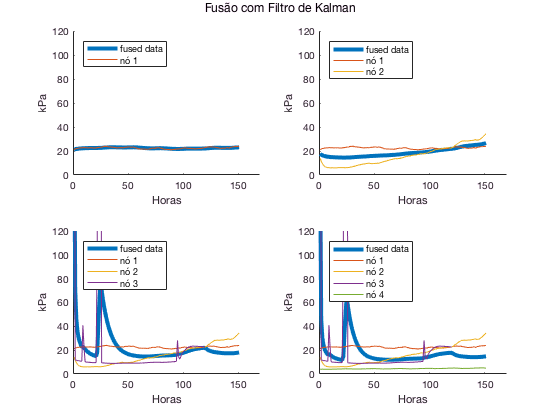

clf % clear current figure
kalmanSubplot2 = figure;
a = subplot(2,2,1);
hold on
plot(sensor2fusedKAF1,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor02value,'DisplayName','nó 1')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
% title(a,'1 nó')
hold off

b = subplot(2,2,2);
hold on
plot(sensor2fusedKAF2,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor02value,'DisplayName','nó 1')
plot(node2.sensor02value,'DisplayName','nó 2')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

c = subplot(2,2,3);
hold on
plot(sensor2fusedKAF3,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor02value,'DisplayName','nó 1')
plot(node2.sensor02value,'DisplayName','nó 2')
plot(node3.sensor02value,'DisplayName','nó 3')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

d = subplot(2,2,4);
hold on
plot(sensor2fusedKAF4,'DisplayName','fused data','LineWidth',4)
plot(node1.sensor02value,'DisplayName','nó 1')
plot(node2.sensor02value,'DisplayName','nó 2')
plot(node3.sensor02value,'DisplayName','nó 3')
plot(node4.sensor02value,'DisplayName','nó 4')
legend('show','Location','northwest')
ylabel('kPa')
xlabel('Horas')
xlim([0 170])
ylim([0 120])
hold off

figtitle('Fusão com Filtro de Kalman');

saveas(kalmanSubplot,'graphs/sensores_45cm_kalman','png');

# Gráfico comparativo de fusão

Plotar gráfico comparativo

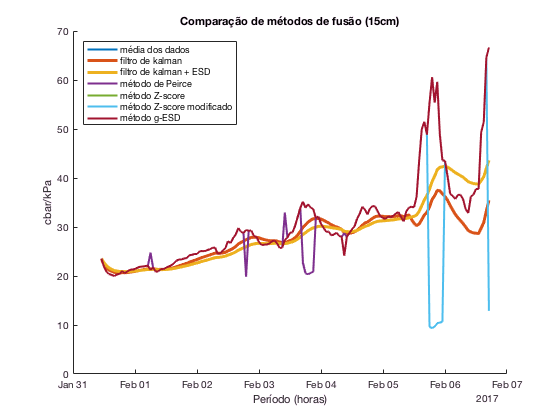

clf

% DateStrings = {'2017-01-31';'2017-02-05'};
% t = datetime(DateStrings,'InputFormat','yyyy-MM-dd');
% DateStrings = {'2017-01-31'};
% dateRangeAlt = datetime({'2017-01-31';'2017-02-01'});

fusionCompare = figure;
hold on
plot(dateRange,sensor1fusedMean,'DisplayName','média dos dados','LineWidth',2);
% semilogy(sensor1fusedMAF6,'DisplayName','média móvel (6)','LineWidth',2);
% semilogy(sensor1fusedMAF12,'DisplayName','média móvel (12)','LineWidth',2);
% plot(dateRange,sensor1fusedMedian,'DisplayName','mediana','LineWidth',2);
plot(dateRange,sensor1fusedKAF4,'DisplayName','filtro de kalman','LineWidth',3);
plot(dateRange,sensor1fusedKAFalt,'DisplayName','filtro de kalman + ESD','LineWidth',3);
plot(dateRange,sensor1fusedPeirce,'DisplayName','método de Peirce','LineWidth',2);
plot(dateRange,sensor1fusedZScore,'DisplayName','método Z-score','LineWidth',2);
plot(dateRange,sensor1fusedMZScore,'DisplayName','método Z-score modificado','LineWidth',2);
plot(dateRange,sensor1fusedESD,'DisplayName','método g-ESD','LineWidth',2);
% plot([0 180],[10 10], 'k--','HandleVisibility','off'); % 0 a 10: solo saturado
% saturado = text(180,5,'saturado','HorizontalAlignment','center');
% set(saturado,'rotation',90);
% umido = text(180,20,'úmido','HorizontalAlignment','center');
% set(umido,'rotation',90);
% plot([0 180],[30 30], 'k--','HandleVisibility','off'); % 10 a 30: solo adequadamente umido (exceto areia fina)
% irrigar1 = text(180,45,'irrigar','HorizontalAlignment','center');
% set(irrigar1,'rotation',90);
% plot([0 180],[60 60], 'k--','HandleVisibility','off'); % 30 a 60: necessita rega
% irrigar2 = text(180,80,'irrigar','HorizontalAlignment','center');
% set(irrigar2,'rotation',90);
% plot([0 180],[100 100], 'k--','HandleVisibility','off'); % 60 a 100: necessita rega (barro pesado)
% seco = text(180,150,'seco','HorizontalAlignment','center');
% set(seco,'rotation',90);
% plot([0 180],[200 200], 'k--','HandleVisibility','off'); % 100 a 200: perigosamente seco
hold off
legend('Location','northwest')
ylabel('cbar/kPa')
xlabel('Período (horas)')


title('Comparação de métodos de fusão (15cm)');
saveas(fusionCompare,'graphs/sensores_comparacao_fusao_15cm','png');

45cm

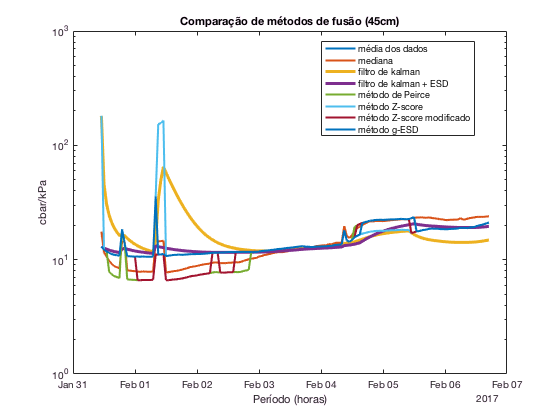

clf
fusionCompare = figure;
semilogy(dateRange,sensor2fusedMean,'DisplayName','média dos dados','LineWidth',2);
hold on
% semilogy(sensor1fusedMAF6,'DisplayName','média móvel (6)','LineWidth',2);
% semilogy(sensor1fusedMAF12,'DisplayName','média móvel (12)','LineWidth',2);
semilogy(dateRange,sensor2fusedMedian,'DisplayName','mediana','LineWidth',2);
semilogy(dateRange,sensor2fusedKAF4,'DisplayName','filtro de kalman','LineWidth',3);
semilogy(dateRange,sensor2fusedKAFalt,'DisplayName','filtro de kalman + ESD','LineWidth',3);
semilogy(dateRange,sensor2fusedPeirce,'DisplayName','método de Peirce','LineWidth',2);
semilogy(dateRange,sensor2fusedZScore,'DisplayName','método Z-score','LineWidth',2);
semilogy(dateRange,sensor2fusedMZScore,'DisplayName','método Z-score modificado','LineWidth',2);
semilogy(dateRange,sensor2fusedESD,'DisplayName','método g-ESD','LineWidth',2);
hold off
legend('Location','best')
ylabel('cbar/kPa')
xlabel('Período (horas)')
title('Comparação de métodos de fusão (45cm)');
saveas(fusionCompare,'graphs/sensores_comparacao_fusao_45cm','png');

75cm

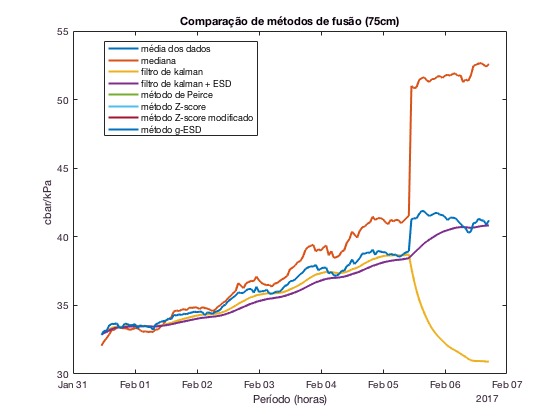

clf
fusionCompare = figure;
plot(dateRange,sensor3fusedMean,'DisplayName','média dos dados','LineWidth',2);
hold on
% semilogy(sensor1fusedMAF6,'DisplayName','média móvel (6)','LineWidth',2);
% semilogy(sensor1fusedMAF12,'DisplayName','média móvel (12)','LineWidth',2);
plot(dateRange,sensor3fusedMedian,'DisplayName','mediana','LineWidth',2);
plot(dateRange,sensor3fusedKAF4,'DisplayName','filtro de kalman','LineWidth',2);
plot(dateRange,sensor3fusedKAFalt,'DisplayName','filtro de kalman + ESD','LineWidth',2);
plot(dateRange,sensor3fusedPeirce,'DisplayName','método de Peirce','LineWidth',2);
plot(dateRange,sensor3fusedZScore,'DisplayName','método Z-score','LineWidth',2);
plot(dateRange,sensor3fusedMZScore,'DisplayName','método Z-score modificado','LineWidth',2);
plot(dateRange,sensor3fusedESD,'DisplayName','método g-ESD','LineWidth',2);
hold off
legend('Location','best')
ylabel('cbar/kPa')
xlabel('Período (horas)')
title('Comparação de métodos de fusão (75cm)');
saveas(fusionCompare,'graphs/sensores_comparacao_fusao_75cm','png')

# Testes

% wrKF
% Yn = sensor1meanOrig(:,1);
% Yn = sensor1fusedMZScore;

x = 1; % initial state value
P = 0.01;
A = 1;
C = 1;
Q = .005;
% R = 1e-4;
R = 0.64;
ss_wrKF.sum_wzxT = 0;                
ss_wrKF.sum_wxxT = 0;
ss_wrKF.sum_xxold = 0;
ss_wrKF.sum_xxoldT = 0;
ss_wrKF.sum_N = 0;
ss_wrKF.sum_wzz = 0;
ss_wrKF.sum_wzx = 0;
ss_wrKF.sum_ExTx = 0;
ss_wrKF.sum_Exxold = 0;
% [sensor1wrkf, weight, S, P, A, C, Q, R, ss] = wrKF_learn_alt(x, sensor1fusedMZScore, P, A, C, Q, R, ss_wrKF);
[sensor1wrkf, ~, ~, ~, ~, ~, ~, ~, ~] = wrKF_learn_alt(x, sensor1fusedMZScore, P, A, C, Q, R, ss_wrKF);
[sensor2wrkf, ~, ~, ~, ~, ~, ~, ~, ~] = wrKF_learn_alt(x, sensor2fusedMZScore, P, A, C, Q, R, ss_wrKF);
[sensor3wrkf, ~, ~, ~, ~, ~, ~, ~, ~] = wrKF_learn_alt(x, sensor3fusedMZScore, P, A, C, Q, R, ss_wrKF);

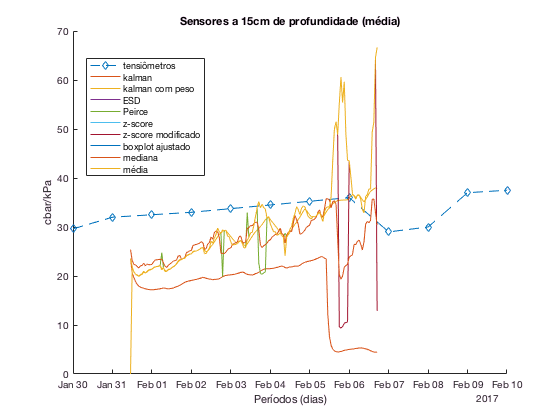

periodoComparacao = datetime({'30/01/2017' '10/02/2017'});

comparacao15cm = figure;
hold on
plot(baterias_Mean.Date,baterias_Mean.baterias_p15cmMean,'--d','DisplayName','tensiômetros');
plot(dateRange,sensor1fusedKAF4,'DisplayName','kalman');
plot(dateRange,sensor1fusedKAFalt,'DisplayName','kalman + ESD','LineWidth',2);
plot(dateRange,sensor1wrkf,'DisplayName','kalman com peso');
plot(dateRange,sensor1fusedESD,'DisplayName','ESD');
plot(dateRange,sensor1fusedPeirce,'DisplayName','Peirce');
plot(dateRange,sensor1fusedZScore,'DisplayName','z-score');
plot(dateRange,sensor1fusedMZScore,'DisplayName','z-score modificado');
plot(dateRange,sensor1fusedBoxAdj,'DisplayName','boxplot ajustado');
plot(dateRange,sensor1fusedMedian,'DisplayName','mediana');
plot(dateRange,sensor1fusedMean,'DisplayName','média');
hold off
xlim(periodoComparacao);
ylabel('cbar/kPa');
xlabel('Períodos (dias)');
title('Sensores a 15cm de profundidade (média)');
legend('show','Location','best');
saveas(comparacao15cm,'graphs/comparativo_metodos_15cm','png');

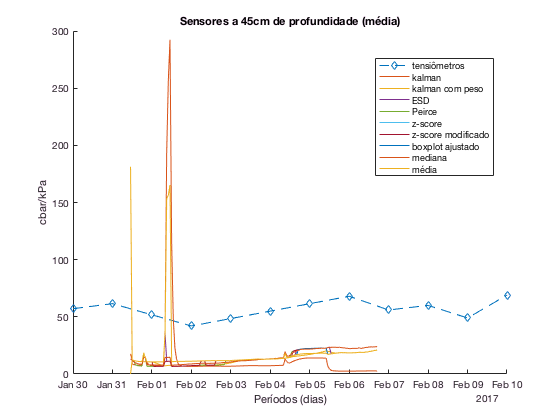

comparacao45cm = figure;
hold on
plot(baterias_Mean.Date,baterias_Mean.baterias_p45cmMean,'--d','DisplayName','tensiômetros');
plot(dateRange,sensor2fusedKAF4,'DisplayName','kalman');
plot(dateRange,sensor2fusedKAFalt,'DisplayName','kalman + ESD','LineWidth',2);
plot(dateRange,sensor2wrkf,'DisplayName','kalman com peso');
plot(dateRange,sensor2fusedESD,'DisplayName','ESD');
plot(dateRange,sensor2fusedPeirce,'DisplayName','Peirce');
plot(dateRange,sensor2fusedZScore,'DisplayName','z-score');
plot(dateRange,sensor2fusedMZScore,'DisplayName','z-score modificado');
plot(dateRange,sensor2fusedBoxAdj,'DisplayName','boxplot ajustado');
plot(dateRange,sensor2fusedMedian,'DisplayName','mediana');
plot(dateRange,sensor2fusedMean,'DisplayName','média');
hold off
xlim(periodoComparacao);
ylabel('cbar/kPa');
xlabel('Períodos (dias)');
title('Sensores a 45cm de profundidade (média)');
legend('show','Location','best');
saveas(comparacao45cm,'graphs/comparativo_metodos_45cm','png');

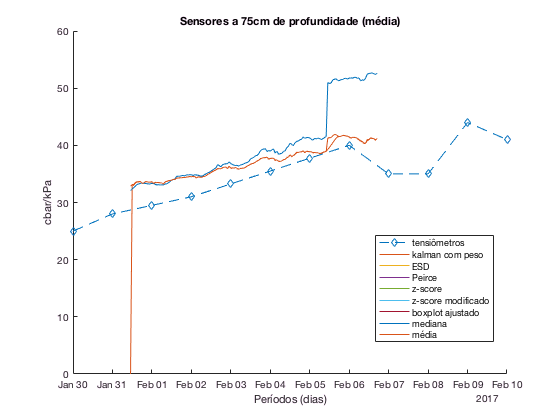

comparacao75cm = figure;
hold on
plot(baterias_Mean.Date,baterias_Mean.baterias_p75cmMean,'--d','DisplayName','tensiômetros');
plot(dateRange,sensor3fusedKAF4,'DisplayName','kalman');
plot(dateRange,sensor3wrkf,'DisplayName','kalman com peso');
plot(dateRange,sensor3fusedKAFalt,'DisplayName','kalman + ESD','LineWidth',2);
plot(dateRange,sensor3fusedESD,'DisplayName','ESD');
plot(dateRange,sensor3fusedPeirce,'DisplayName','Peirce');
plot(dateRange,sensor3fusedZScore,'DisplayName','z-score');
plot(dateRange,sensor3fusedMZScore,'DisplayName','z-score modificado');
plot(dateRange,sensor3fusedBoxAdj,'DisplayName','boxplot ajustado');
plot(dateRange,sensor3fusedMedian,'DisplayName','mediana');
plot(dateRange,sensor3fusedMean,'DisplayName','média');
hold off
xlim(periodoComparacao);
ylabel('cbar/kPa');
xlabel('Períodos (dias)');
title('Sensores a 75cm de profundidade (média)');
legend('show','Location','best');
saveas(comparacao75cm,'graphs/comparativo_metodos_75cm','png');

% xlim(['30/01/2017' '02/10/2017'])

## Leituras do Tensiometros

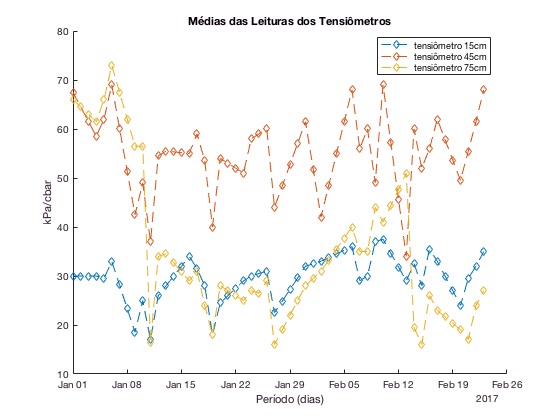

tensiometrosGraph = figure;
hold on;
plot(baterias_Mean.Date,baterias_Mean.baterias_p15cmMean,'--d','DisplayName','tensiômetro 15cm');
plot(baterias_Mean.Date,baterias_Mean.baterias_p45cmMean,'--d','DisplayName','tensiômetro 45cm');
plot(baterias_Mean.Date,baterias_Mean.baterias_p75cmMean,'--d','DisplayName','tensiômetro 75cm');
hold off;
xlabel('Período (dias)');
ylabel('kPa/cbar');
title('Médias das Leituras dos Tensiômetros');
legend('show','Location','best');
saveas(tensiometrosGraph,'graphs/manuais/leituras-tensiometros','png');

function plotar_sensores(period,sensor,sensorFused,depth,type,plotTitle,legendPosition,plotYlog)
    if nargin < 8
        plotYlog = false;
    end
    grafico = figure;
    ylim([-5; Inf]);
    if plotYlog == false
        plot(period,sensor)
        hold on
        plot(period,sensorFused,'LineWidth',4);
    else
        semilogy(period,sensor)
        hold on
        semilogy(period,sensorFused,'LineWidth',4);
    end
%     DateStrings = {'2017-01-31 11:00';'2017-02-05 10:00'};
%     t = datetime(DateStrings,'InputFormat','yyyy-MM-dd hh:mm');
%     saturado = text(8,5,'saturado','HorizontalAlignment','center');
    % set(saturado,'rotation',90);
%     plot(t,[10 10], 'k--','HandleVisibility','off'); % 0 a 10: solo saturado
%     umido = text(8,20,'úmido','HorizontalAlignment','center');
%     set(umido,'rotation',90);
%     plot(t,[30 30], 'k--','HandleVisibility','off'); % 10 a 30: solo adequadamente umido (exceto areia fina)
%     irrigar1 = text(8,45,'irrigar','HorizontalAlignment','center');
%     set(irrigar1,'rotation',90);
%     plot(t,[60 60], 'k--','HandleVisibility','off'); % 30 a 60: necessita rega
%     irrigar2 = text(8,80,'irrigar','HorizontalAlignment','center');
%     set(irrigar2,'rotation',90);
%     plot(t,[100 100], 'k--','HandleVisibility','off'); % 60 a 100: necessita rega (barro pesado)
%     seco = text(8,150,'perigosamente seco','HorizontalAlignment','center');
%     set(seco,'rotation',90);
%     plot(t,[200 200], 'k--','HandleVisibility','off'); % 100 a 200: perigosamente seco
    global dateSensorDeath;
    vline(dateSensorDeath,'k:'); % indicativo da morte do nó 3
    hold off
    legend('nó 1','nó 2','nó 3','nó 4','fusão','location',legendPosition)
    if plotYlog == false
        ylabel('kPa/cbar')
    else
        ylabel('kPa/cbar (log)')
    end
    xlabel('Período (dias)')
    titleDepth = sprintf('Sensores a %s de profundidade',depth);
    title({plotTitle,titleDepth});
    filename = sprintf('graphs/sensores_%s_%s',depth,type);
    saveas(grafico,filename,'png')
    
%     function plotsigs(pos, sig1, sig2, sig1label)
% subplot(3,1,pos)
% hold on
% plot(sig1, 'k')
% plot(sig2, 'r')
% legend({sig1label, 'Estimated'})
% ylim([15 40])
% hold off
end

function plotar_metodo(period,sensor,methodData,type,graphTitle,outlierCount,legendPosition,outlierIndex)
    if nargin < 8
        outlierIndex = NaN;
    end
    
    grafico = figure;
%     semilogy(period,sensor);
    hold on
    plot(period,sensor);
    plot(period,methodData,'LineWidth',4);
    if ~isnan(outlierIndex)
        for i = 1:size(sensor,1)
        	if (outlierIndex(i) ~= 0)
        		plot(period(i),sensor(i,outlierIndex(i)),'LineStyle','none','Marker','o','MarkerEdgeColor','red');
        	end
        end
    end
    hold off
    titleOutliers = sprintf('Total de outliers removidos: %d',outlierCount);
    methodName = sprintf('Fusão utilizando método %s',graphTitle);
    title({methodName,titleOutliers});
    xlabel('Período (dias)');
    ylabel('kPa/cbar');
    legend('nó 1','nó 2','nó 3','nó 4','fusão','outlier','location',legendPosition)
    filename = sprintf('graphs/sensores_%s',type);
    saveas(grafico,filename,'png');
end

function plotar_metodo_log(period,sensor,methodData,type,graphTitle,outlierCount,legendPosition,outlierIndex)
    if nargin < 8
        outlierIndex = NaN;
    end
    
    grafico = figure;
    semilogy(period,sensor);
    hold on
    semilogy(period,methodData,'LineWidth',4);
    if ~isnan(outlierIndex)
        for i = 1:size(sensor,1)
        	if (outlierIndex(i) ~= 0)
        		semilogy(period(i),sensor(i,outlierIndex(i)),'LineStyle','none','Marker','o','MarkerEdgeColor','red');
        	end
        end
    end
    hold off
    titleOutliers = sprintf('Total de outliers removidos: %d',outlierCount);
    methodName = sprintf('Fusão utilizando método %s',graphTitle);
    title({methodName,titleOutliers});
    xlabel('Período (dias)');
    ylabel('kPa/cbar (log)');
    legend('nó 1','nó 2','nó 3','nó 4','fusão','outlier','location',legendPosition)
    filename = sprintf('graphs/sensores_%s',type);
    saveas(grafico,filename,'png');
end

function plotar_metodo_alt(period,sensor,methodData,type,graphTitle,outlierCount,legendPosition,outlierIndex)
    grafico = figure;
    hold on
    plot(period,sensor);
    plot(period,methodData,'LineWidth',4);
    for i = 1:size(outlierIndex,1)
        plot(period(outlierIndex(i,1)),outlierIndex(i,2),'LineStyle','none','Marker','o','MarkerEdgeColor','red')
    end
    hold off
    titleOutliers = sprintf('Total de outliers removidos: %d',outlierCount);
    methodName = sprintf('Fusão utilizando método %s',graphTitle);
    title({methodName,titleOutliers});
    xlabel('Período (dias)');
    ylabel('kPa/cbar');
    legend('nó 1','nó 2','nó 3','nó 4','fusão','outlier','location',legendPosition)
    filename = sprintf('graphs/sensores_%s',type);
    saveas(grafico,filename,'png');
end

function plotar_metodo_alt_log(period,sensor,methodData,type,graphTitle,outlierCount,legendPosition,outlierIndex)
    grafico = figure;
    semilogy(period,sensor);
    hold on
    semilogy(period,methodData,'LineWidth',4);
    for i = 1:size(outlierIndex,1)
        semilogy(period(outlierIndex(i,1)),outlierIndex(i,2),'LineStyle','none','Marker','o','MarkerEdgeColor','red')
    end
    hold off
    titleOutliers = sprintf('Total de outliers removidos: %d',outlierCount);
    methodName = sprintf('Fusão utilizando método %s',graphTitle);
    title({methodName,titleOutliers});
    xlabel('Período (dias)');
    ylabel('kPa/cbar (log)');
    legend('nó 1','nó 2','nó 3','nó 4','fusão','outlier','location',legendPosition)
    filename = sprintf('graphs/sensores_%s',type);
    saveas(grafico,filename,'png');
end